th = 25

th = 25

theta = th:th + 179; % 投影角度
I = File2;
I_2 = iradon(File2, theta, 'linear', 'Ram-Lak', 1, 512);
I2 = imresize(I_2,0.5)

I2 =     0.0137    0.0130    0.0107    0.0026    0.0053    0.0118    0.0081    0.0068    0.0010    0.0116    0.0165    0.0148    0.0007   -0.0064    0.0126    0.0168    0.0143    0.0009   -0.0015    0.0169    0.0140    0.0056   -0.0006    0.0127    0.0065   -0.0002    0.0055    0.0236    0.0140    0.0040   -0.0043    0.0018    0.0156    0.0153   -0.0024    0.0059    0.0139    0.0137   -0.0079    0.0026    0.0215    0.0192   -0.0019    0.0019    0.0085    0.0085    0.0049    0.0156    0.0144    0.0047
    0.0104    0.0123    0.0084    0.0053   -0.0008    0.0136    0.0148    0.0104    0.0010   -0.0017    0.0141    0.0143    0.0138    0.0038    0.0016    0.0091    0.0112    0.0104   -0.0014    0.0125    0.0140    0.0109   -0.0014    0.0036    0.0169    0.0083   -0.0074    0.0079    0.0233    0.0166    0.0031   -0.0078    0.0074    0.0111    0.0098    0.0038    0.0145    0.0072    0.0048   -0.0023    0.0128    0.0138    0.0098    0.0036    0.0132    0.0041   -0.0046    0.0084    0.0242    

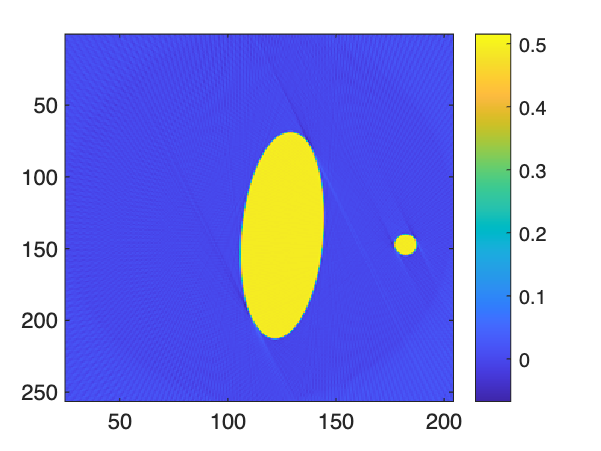

imagesc(theta, 1:size(I2,1), I2);
colorbar

re = I2 - File1;
sum(sum(abs(re)))

ans = 1.0365e+04

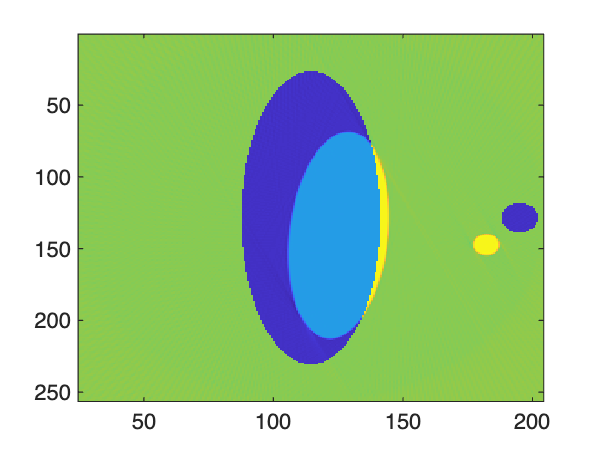

imagesc(theta, 1:size(re,1), re);

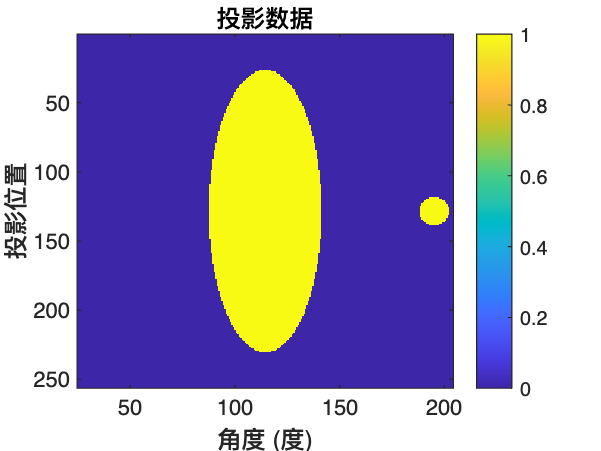

imagesc(theta, 1:size(File1,1), File1);
% imagesc(theta, 1:size(R,1), File2);
title('投影数据');
xlabel('角度 (度)');
ylabel('投影位置');
colorbar;